# Recording the Audio

Before we can actually use the audiorecorder function, we must define some variables to be used

filename = 'ui2.wav';
Fs = 44100; 
nBits = 8; 
nChannels = 1; 
ID = -1; % default audio input device

Now we record our audio file and save it in a .wav format for further use, so we don't have to re-record everytime

recObj = audiorecorder(Fs,nBits, nChannels, ID);


disp('Start speaking.')
recordblocking(recObj,T);
disp('End of Recording.');

play(recObj); % Checking to see if our audio was correctly picked up


doubleArray = getaudiodata(recObj);
plot(doubleArray);
title('Audio Signal (Double)');

audiowrite(filename, doubleArray, Fs);

# Reading in the Audio

Now that we have saved our audio file in a .wav format, we may invoke the audioread function to read it evertime our script is run

[x, Fs] = audioread('ui2.wav');
L = length(x);
T = L / Fs;
t = linspace(0, T, L);


# Plotting the Spectrum

First we will define a function to assist in the plotting of frequencies

Let us get the one sided frequency spectrum of our sample signal

% One sided frequency transform of x
P1X = offt(x, L);

% One sided frequency array
f = Fs * (1:(L/2+1)) / L; 

The following variable holds the endpoint of the frequency we want to see. I have defined this to better see the part of the spectrum worth looking at.

FREQUENCY_END = 15000;

Now we will plot the signal and its spectrum

subplot(2, 1, 1);
plot(t, x);
title('Audio Signal x(t)')
xlabel('time (t)')
ylabel('x(t)')

subplot(2, 1, 2);
plot(2 * pi * f(1:FREQUENCY_END), P1X(1:FREQUENCY_END));
title('Single Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X(\Omega)|')

# Designing a Low Pass Analog Filter

Now we are going to design a third order butterworth filter to "clean" our signal before sampling it. This is done to prevent aliasing as sometimes the highest frequency components of a signal are simply noise, or they do not contain useful data. 

## The butterworth filter and the cutoff frequency

We use a third order filter because

We use 5kHz cutoff frequency because

We will also plot the frequency response of these filters

fc = 5000;  % Cutoff frequency
[b, a] = butter(3, fc/(Fs/2));

freqz(b, a);


## Plotting the signal and its spectrum

Let us now look at our signal after it passing through our filter

xf = filter(b, a, x);
Xf = offt(xf, L);

subplot(2, 1, 1);
plot(t, xf);
title('Audio Signal x_f(t)')
xlabel('time (t)')
ylabel('x_f(t)')

subplot(2, 1, 2);
plot(2 * pi * f(1:FREQUENCY_END), Xf(1:FREQUENCY_END));
title('Single Sided Spectrum of X_f(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X_f(\Omega)|')

# Applying the Zero-Order Hold filter

Now we are ready to sample our continous signal into discrete instances.

We should be careful to choose a sampling period T, such that aliasing does not occur

For this reason F_sample should be greater than Fs/2.

x_n = zoh(xf, 2);
Xn = fftshift(fft(x_n));
f2 = Fs * (-L/2:L/2-1) / L;

## Plotting the signal and its spectrum

Let us see our signal and its spectrum after being converted

subplot(2, 1, 1);
stem(t(1:500), x_n(1:500)); % Plotting a section as it does get jumbled up
title('Audio Signal x[n]')
xlabel('time (t)')
ylabel('x[n]')

subplot(2, 1, 2);
plot(2 * pi * f2, abs(Xn));
title('Double Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X(\Omega)|')


## Wrong way to sample

Let us take a look at what would happen if we do not take care of our Nyquist requirements

x_wrong = zoh(xf, 20);
X_wrong = fftshift(fft(x_wrong));

subplot(2, 1, 1);
stem(t(1:500), x_wrong(1:500)); %Plotting a section as it does get jumbled up
title('Audio Signal x[n]')
xlabel('time (t)')
ylabel('x[n]')

subplot(2, 1, 2);
plot(2 * pi * f2, abs(X_wrong));
title('Double Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X(\Omega)|')

# Downsampling

Now let us downsample our discrete signal by a factor of M, and see what our signal looks like in comparison to the original. For this we will use the decimate function.

The decimate function works by taking a sample after ever M instance and storing it in an array of size (L/2)

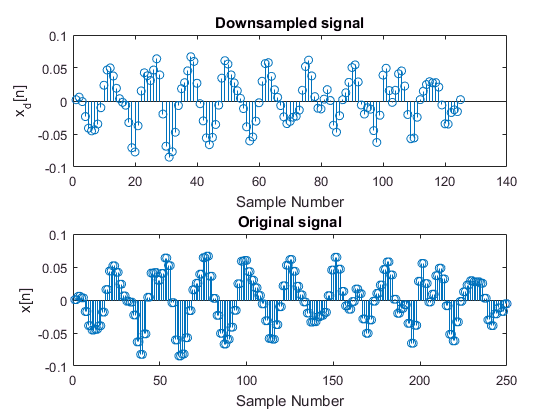

M = 2; % Downsampling Factor
x_d = decimate(x_n, M);
t_d = linspace(0,T,length(x_d));
Xd = offt(x_d, length(x_d));

subplot(2, 1, 1);
stem(x_d(1:125))
title('Downsampled signal');
xlabel('Sample Number')
ylabel('x_d[n]')

subplot(2, 1, 2);
stem(x_n(1:250))
title('Original signal');
xlabel('Sample Number')
ylabel('x[n]')

Lets compare the spectrum of our signal before and after downsampling

subplot(2, 1, 1);
plot(2 * pi * f(1:FREQUENCY_END), abs(Xn(1:FREQUENCY_END)));
title('Single Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X_f(\Omega)|')

subplot(2, 1, 2);
plot(M * 2 * pi * f(1:FREQUENCY_END), Xd(1:FREQUENCY_END));
title('Single Sided Spectrum of X(\Omega)')
xlabel('frequency (\Omega)')
ylabel('|X_d(\Omega)|')




# Adding noise

Next we add noise to our downsampled signal

First let us take a look at the noise

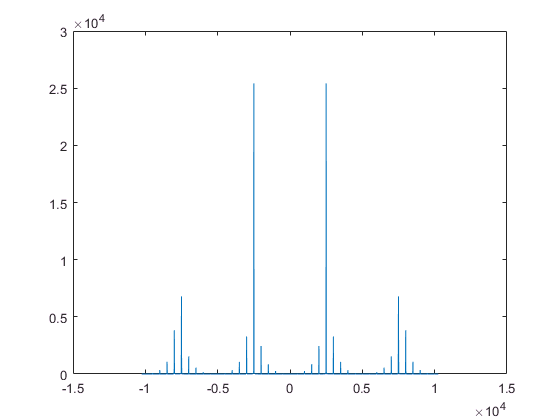

[xnoise, Fsnoise] = audioread('noise.wav');
tnoise = linspace(0,T,length(xnoise));
Lnoise = length(xnoise);
fnoise = Fsnoise * (-Lnoise/2:Lnoise/2-1) / Lnoise;
Xnoise = fftshift(fft(xnoise));
Xnoise = abs(Xnoise);
plot(fnoise, Xnoise);

[a idx] = max(Xnoise)

a = 2.5419e+04

idx = 15501

f(idx)

ans = 7.7505e+03

xown = -sin(2*pi*14300*t);
[maxnoise, idx] = max(Xnoise);
f2(idx)

ans = -14300

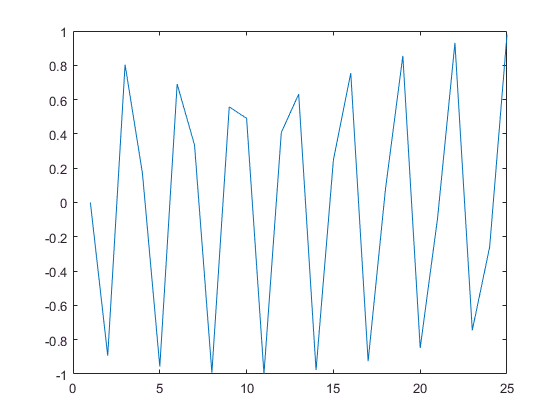

%plot(t(1:25),xown(1:25));
plot(xown(1:25));

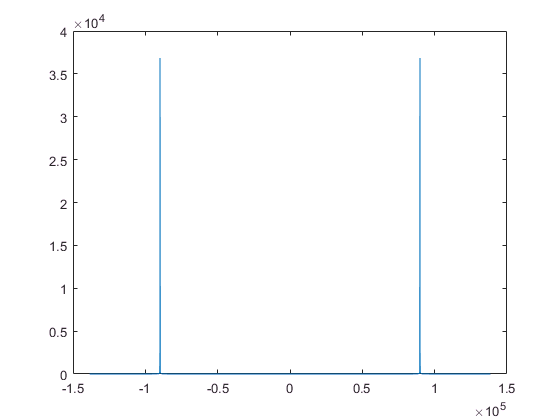

Xown = fftshift(fft(xown));
plot(2*pi*f2, abs(Xown));

# Making a low pass filter 

Now we will make a low pass filter to cut hight frequency noise as much as we can

fc_noise = 

# Upsampling

Now that we have finished filtering the signal, we are ready to upsample it.

We will be using the predefined interp function for this. 

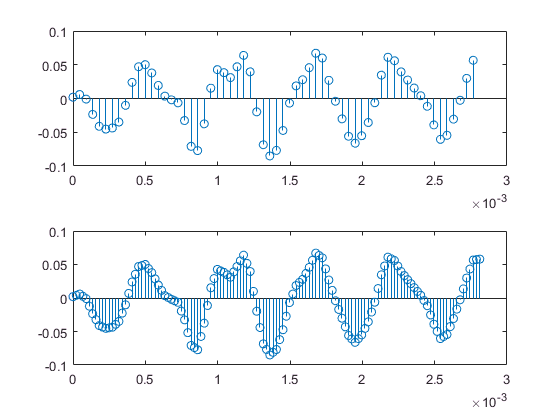

U = 2; % Upsampling factor
xu = interp1(t_d, x_d, t); %Replace t_d and x_d with output from low pass filter when you get a chance
subplot(2,1,1);
stem(t_d(1:62),x_d(1:62));

subplot(2,1,2);
stem(t(1:125),xu(1:125));

## Comparing the spectrums before and after upsampling